## Objective

## Plot and visualize the circulant matrix from real-time target image taken from RGB camera

clear all;
clc;


Read a sample image and crop parts of the image

srishti_path = 'data/Benchmark/ASrishtialone/img/00180.jpg';
im_rgb = imread(srishti_path);
im_rgb = rgb2gray(im_rgb);

% Create a m x n x k dimention aray from the image crops
% m x n is the size of each individual matrix block a
% k x k is the circulant pattern
I2 = imcrop(im_rgb, 1.0e+03 * [1.0785    0.3605+(0*0.031)    0.0290    0.0290]);
I2(:,:,2) = imcrop(im_rgb, 1.0e+03 * [1.0785    0.3605+(1*0.031)    0.0290    0.0290]);
I2(:,:,3) = imcrop(im_rgb, 1.0e+03 * [1.0785    0.3605+(2*0.031)    0.0290    0.0290]);
I2(:,:,4) = imcrop(im_rgb, 1.0e+03 * [1.0785    0.3605+(3*0.031)    0.0290    0.0290]);


Plot the original image with the cropped images to be circularly shifted

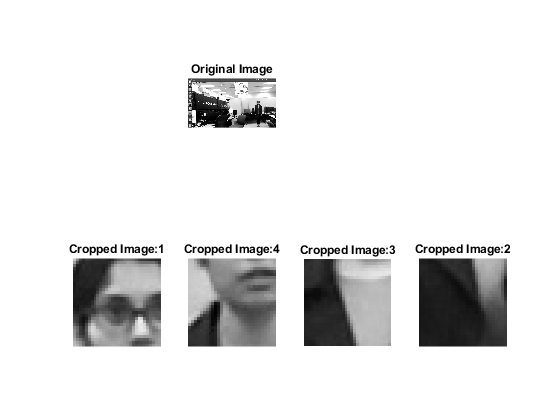

figure();
subplot(2,4,2)
imshow(im_rgb)
title('Original Image')

subplot(2,4,5)
imshow(I2(:,:,1))
title('Cropped Image:1')

subplot(2,4,6)
imshow(I2(:,:,2))
title('Cropped Image:4')

subplot(2,4,7)
imshow(I2(:,:,3))
title('Cropped Image:3')

subplot(2,4,8)
imshow(I2(:,:,4))
title('Cropped Image:2')

Define the first row of the circulant matrix. Here, $M\;x\;N$  is the size of each individual matrix block and we are making a $K\;x\;K$ circulant pattern

I2_size = size(I2) % siz of the image

I2_size =     30    30     4


M = I2_size(1)

M = 30

N = I2_size(2)

N = 30

K = I2_size(3)

K = 4


A = I2;
% Coefficients for block circulant
Ac = permute(A, [1 3 2]);
Ac = cat(2, Ac(:, 2:K, :), Ac);
% Create the block-circulant matrix using convn
I = reshape(eye(K), [1 K 1 K]);
C = convn(I, Ac);
C = reshape(C(:, K:(2*K-1), :, :), [M*K, N*K]);
disp(C);

  Columns 1 through 27

   197   133    65    42    58    54    47    43    41    42    45    39    34    40    66    87    97   112   113   111   103    85    65    55    53    51    45
   160    79    40    37    45    42    38    41    42    40    40    39    48    75   113   139   142   145   158   156   150   136   120   112   111   110   111
   104    33    32    46    41    41    36    39    38    36    33    37    65   120   161   178   172   173   174   174   174   169   160   157   159   159   166
    53    25    33    45    38    42    37    36    36    37    29    47    91   153   182   191   183   185   181   183   187   187   183   180   179   179   177
    36    24    35    38    38    40    37    36    38    39    30    61   109   162   182   195   191   187   185   186   190   192   188   185   183   182   180
    27    27    37    35    40    38    37    38    41    38    40    67   109   158   181   194   193   188   190   189   192   195   192   190   190   191   18

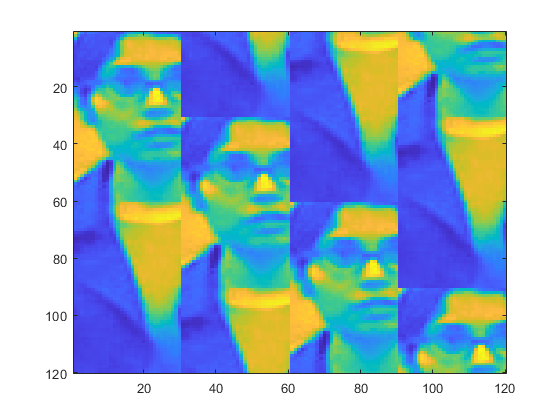

figure();
imagesc(C);

### Plot the HOG features of the cropped patch

features.hog_orientations = 9;
cell_size = 4;

for i=1:4
    %HOG features, from Piotr's Toolbox
    x = double(fhog(single(I2(:,:,i)) / 255, cell_size, features.hog_orientations));
    x(:,:,end) = [];  %remove all-zeros channel ("truncation feature")
    im_hog(:,:,i) = x(:,:,31);
end

Plot the original image with the cropped images to be circularly shifted

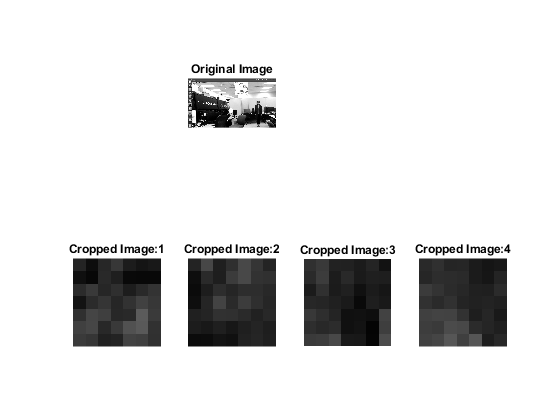

figure();
subplot(2,4,2)
imshow(im_rgb)
title('Original Image')

subplot(2,4,5)
imshow(im_hog(:,:,1))
title('Cropped Image:1')

subplot(2,4,6)
imshow(im_hog(:,:,2))
title('Cropped Image:2')

subplot(2,4,7)
imshow(im_hog(:,:,3))
title('Cropped Image:3')

subplot(2,4,8)
imshow(im_hog(:,:,4))
title('Cropped Image:4')

im_hog_size = size(im_hog) % siz of the image

im_hog_size =      7     7     4


M = im_hog_size(1)

M = 7

N = im_hog_size(2)

N = 7

K = im_hog_size(3)

K = 4


% Coefficients for block circulant
Ac = permute(im_hog, [1 3 2]);
Ac = cat(2, Ac(:, 2:K, :), Ac);
% Create the block-circulant matrix using convn
I = reshape(eye(K), [1 K 1 K]);
C = convn(I, Ac);
C = reshape(C(:, K:(2*K-1), :, :), [M*K, N*K]);
disp(C);

  Columns 1 through 16

    0.1411    0.0522    0.1554    0.2181    0.1130    0.0803    0.0950    0.1615    0.1891    0.1463    0.1495    0.1088    0.0824    0.0970    0.1909    0.2242
    0.0613    0.0274    0.1607    0.1241    0.0366    0.0351    0.0345    0.1522    0.1763    0.1758    0.1669    0.1059    0.0894    0.1417    0.1645    0.2349
    0.1690    0.2265    0.1492    0.1847    0.1147    0.1618    0.2020    0.2317    0.1993    0.1693    0.1552    0.1285    0.1226    0.1690    0.1056    0.1900
    0.0754    0.1712    0.2103    0.1521    0.1977    0.2557    0.2177    0.1939    0.1672    0.1928    0.1420    0.1310    0.1395    0.1250    0.1547    0.1482
    0.1904    0.2717    0.2469    0.1538    0.1609    0.3558    0.2295    0.2507    0.2626    0.2605    0.1963    0.1200    0.1495    0.1013    0.2214    0.1804
    0.2506    0.2750    0.1579    0.2252    0.3183    0.3493    0.1932    0.2388    0.2296    0.2955    0.2824    0.1682    0.1447    0.1216    0.1804    0.1587
    0.2285

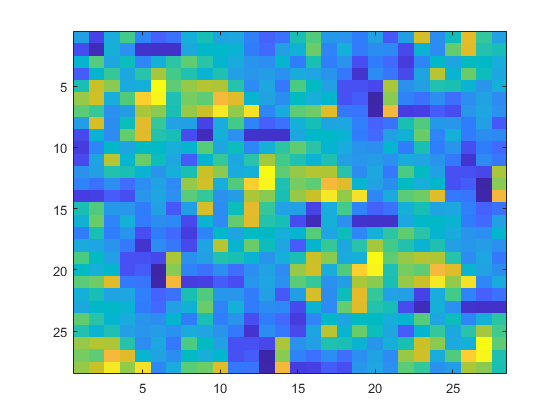

figure();
imagesc(C)